TODO:

Ta hänsyn till det vita (i paletten)

Hämta 100 färger från bilden istället (också)

Optimering för att ta bort ett antal färger 100->50 från paletten

Tre kvalitetsmått

"Annan typ av optimering"

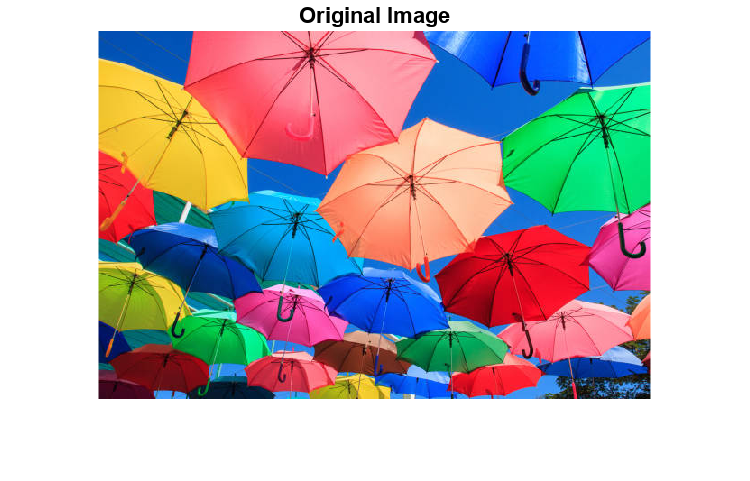

clear
clf

% Settings
partitionSize = 10;
hexFile = 'diverse-natural.hex';
shapeFile = 'circle.png';
imageFile = 'umbrellas.jpg';

im = imread(imageFile);
imshow(im);
title('Original Image');

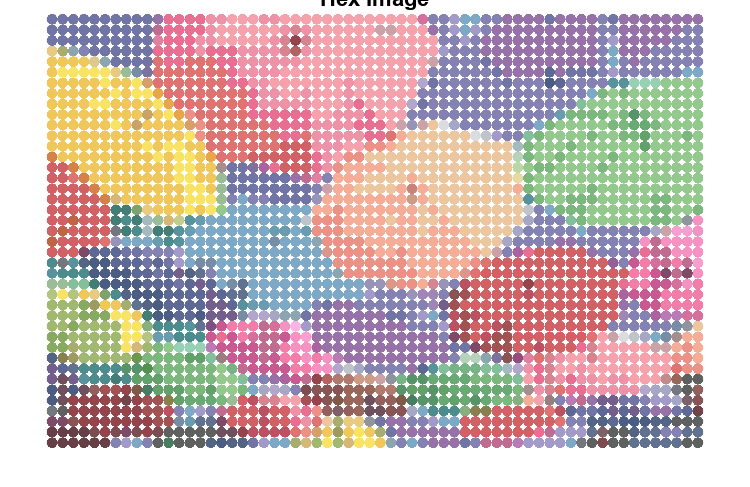


outputHex = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'meanColorDistance');
imshow(outputHex);
title('Hex Image');

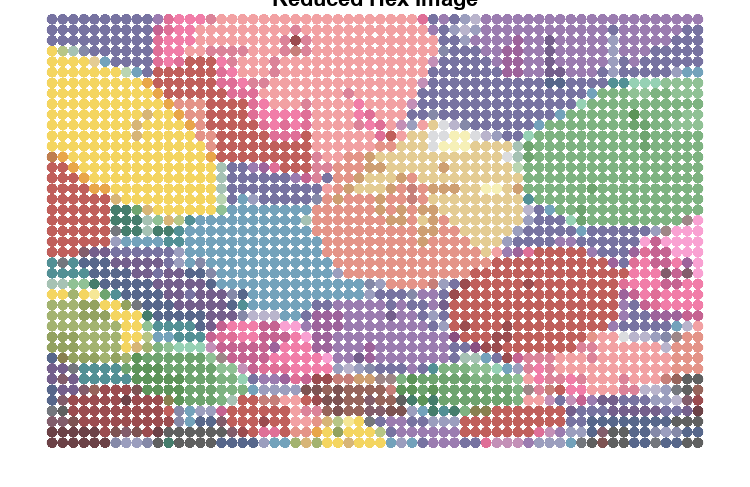


outputReducedColor = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'globalReduction');
imshow(outputReducedColor);
title('Reduced Hex Image');

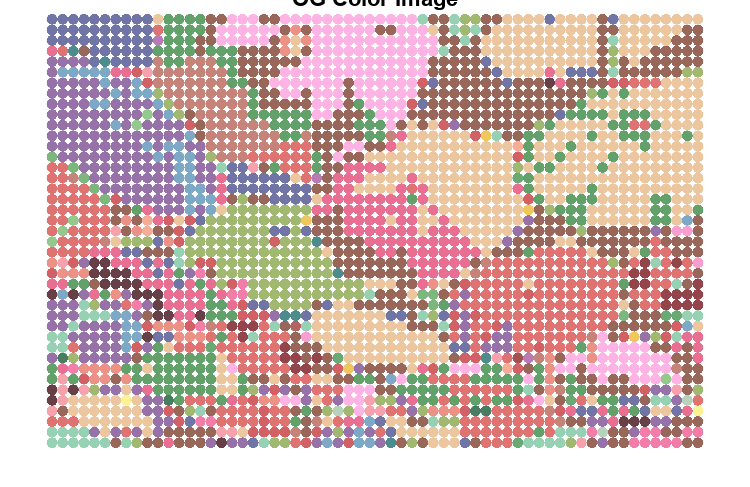


outputOGColor = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'imageColorDistance');
imshow(outputOGColor);
title('OG Color Image');

%% Not working SCIELAB
imLab = rgb2lab(im2double(im));
outputHexLab = rgb2lab(im2double(outputHex));
outputOGColorLab = rgb2lab(im2double(outputOGColor));

% imresize bicubic

% 
% sampPerDeg = 141.21 * 500/25.4 * tan(pi/180);
% 
% fullmetric = scielab(sampPerDeg, rgb2xyz(outputOGColor), rgb2xyz(outputHex), [95.05, 100, 108.9], 'xyz');
% mean(mean(fullmetric))
% 
% % e = computeDeltaE(im, outputHex);
% % mean(e)
% % max(e)

% ??
deltaE = sqrt((outputOGColorLab(:,:,1) - outputHexLab(:,:,1)).^2 + (outputOGColorLab(:,:,2) - outputHexLab(:,:,2)).^2 + (outputOGColorLab(:,:,3) - outputHexLab(:,:,3)).^2);
mean(mean(deltaE))

ans = 30.1061

max(max(deltaE))

ans = 89.5392